clear;
clc;
cla;

% normal data
data = load("d00.dat");
sz = size(data)

sz =     52   500


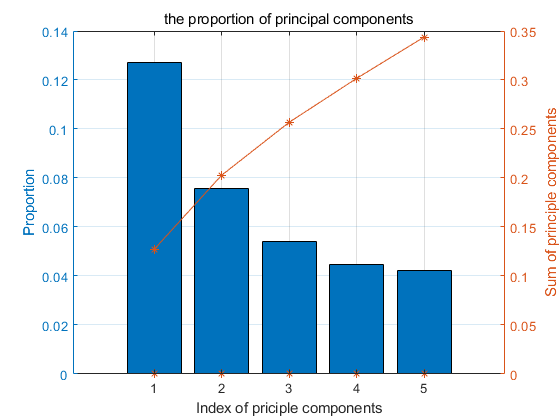

% 52 features
if sz(1) < sz(2)
    data = data';
end
% size: number x feature
data_norm = normalize(data, 1, 'zscore');
cov = data_norm' * data_norm ./ max(size(data)); % covariance matrix
% get the vector and eig value, and sort
[vector, value] = eig(cov);
[~, idx] = sort(diag(value), 'descend');
v = diag(value(idx, idx));
% loading vectors
P = vector(:, idx); 
% score matrix 
T = data_norm * P;

value_prop = v ./ sum(v);
value_percentage = zeros(5);
for j = 1:5
    value_percentage(j) = sum(value_prop(1:j));
end

figure(1);
yyaxis left;
bar(value_prop(1:5));
set(gca, 'XTickLabel', {'1', '2', '3', '4', '5'}, 'fontsize', 10);
xlabel('Index of priciple components');
ylabel('Proportion');
hold on;
yyaxis right;
% scatter(1:5, value_percentage);
plot(value_percentage, 'Marker',"*");
ylabel('Sum of principle components');
grid on;
title('the proportion of principal components');
saveas(gca, 'fig/proportion.jpg');

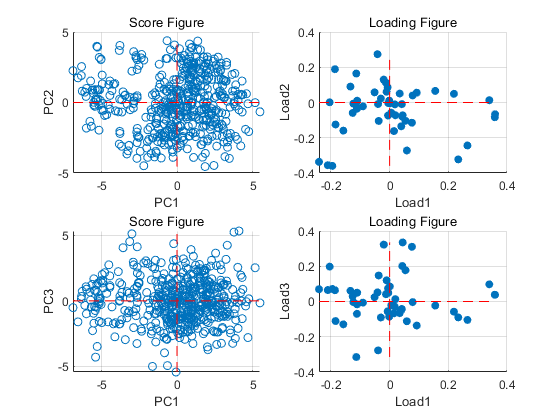


figure('Name', 'd00_normal_data');
subplot(221);
scatter(T(:, 1), T(:, 2));
grid on;
line([min(T(:, 1)), max(T(:, 1))], [0, 0], 'LineStyle','--', 'color', 'red');
line([0, 0], [min(T(:, 2)), max(T(:, 2))], 'LineStyle','--', 'color', 'red');
xlabel('PC1');
ylabel('PC2');
title('Score Figure');

subplot(222);
scatter(P(:, 1), P(:, 2), 'filled');
grid on;
line([min(P(:, 1)), max(P(:, 1))], [0, 0], 'LineStyle','--', 'color', 'red');
line([0, 0], [min(P(:, 2)), max(P(:, 2))], 'LineStyle','--', 'color', 'red');
xlabel('Load1');
ylabel('Load2');
title('Loading Figure');

subplot(223);
scatter(T(:, 1), T(:, 3));
grid on;
line([min(T(:, 1)), max(T(:, 1))], [0, 0], 'LineStyle','--', 'color', 'red');
line([0, 0], [min(T(:, 3)), max(T(:, 3))], 'LineStyle','--', 'color', 'red');
xlabel('PC1');
ylabel('PC3');
title('Score Figure');

subplot(224);
scatter(P(:, 1), P(:, 3), 'filled');
grid on;
line([min(P(:, 1)), max(P(:, 1))], [0, 0], 'LineStyle','--', 'color', 'red');
line([0, 0], [min(P(:, 3)), max(P(:, 3))], 'LineStyle','--', 'color', 'red');
xlabel('Load1');
ylabel('Load3');
title('Loading Figure');
saveas(gca, 'fig/normal_data.jpg');

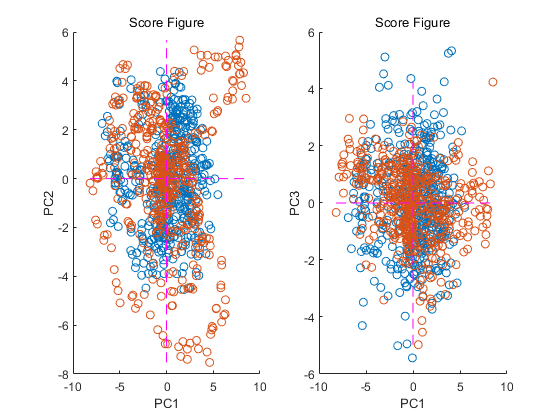

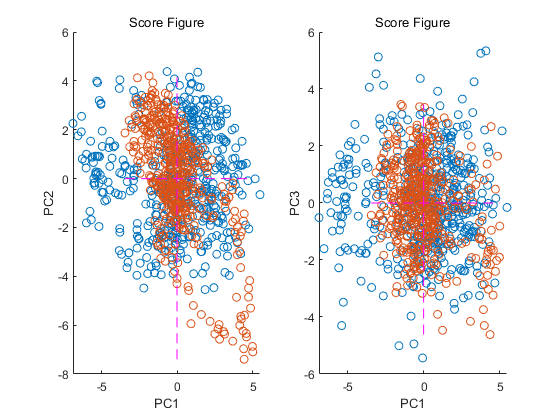

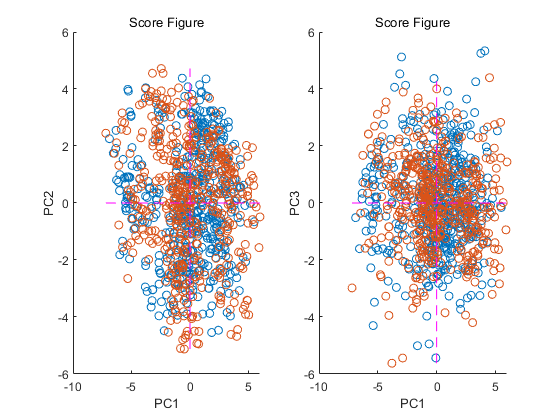

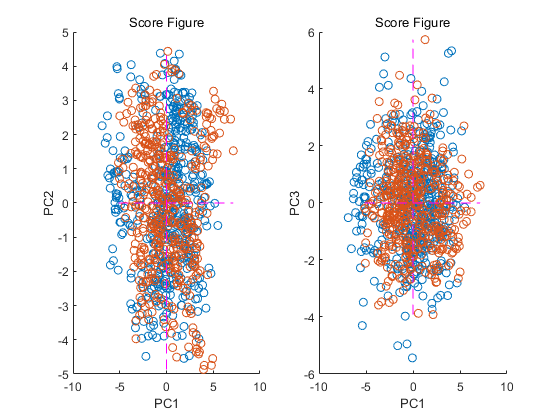

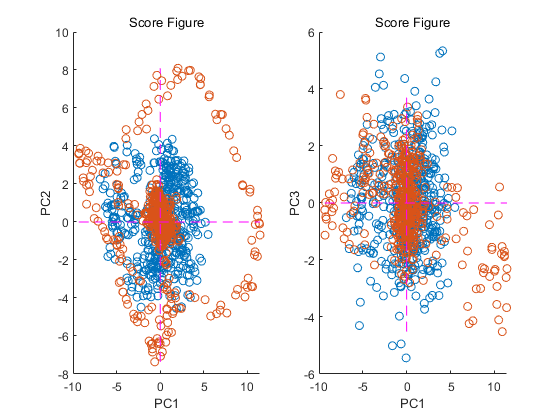

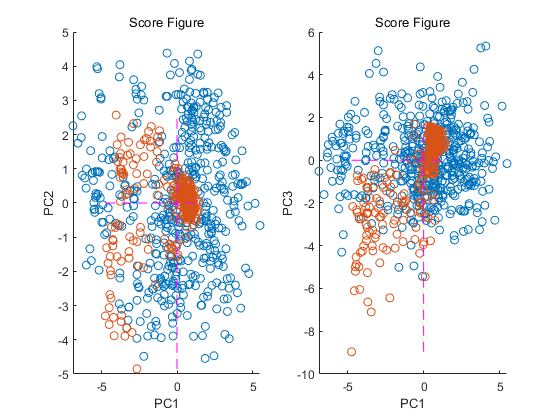

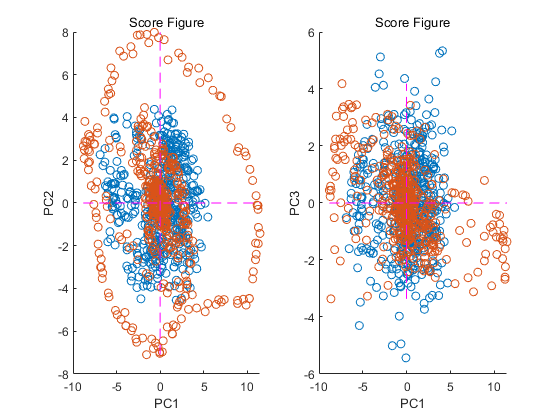

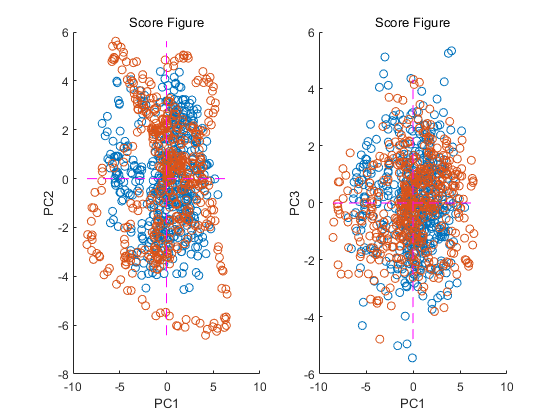

for i = 1:21
    if i < 10
        name = "d0" + num2str(i);
    else
        name = "d" + num2str(i);
    end
    data = load(name+".dat");
    sz = size(data);
    % 52 features
    if sz(1) < sz(2)
        data = data';
    end
    data_norm = normalize(data, 1, 'zscore');
    T_error = data_norm * P;
    figure('Name', name);
    subplot(121);
    scatter(T(:, 1), T(:, 2));
    hold on;
    scatter(T_error(:, 1), T_error(:, 2));
%     plot(T_error(1:5:end, 1), T_error(1:5:end, 2));
%     for n = 1:5:length(T_error)
%         text(T_error(n, 1)+0.05, T_error(n, 2), num2str(n));
%     end
    line([min(T_error(:, 1)), max(T_error(:, 1))], [0, 0], 'LineStyle','--', 'color', 'magenta');
    line([0, 0], [min(T_error(:, 2)), max(T_error(:, 2))], 'LineStyle','--', 'color', 'magenta');
    xlabel('PC1');
    ylabel('PC2');
    title('Score Figure');
    
    subplot(122);
    scatter(T(:, 1), T(:, 3));
    hold on;
    scatter(T_error(:, 1), T_error(:, 3));
%     plot(T_error(1:5:end, 1), T_error(1:5:end, 3));
%     for n = 1:5:length(T_error)
%         text(T_error(n, 1)+0.05, T_error(n, 3), num2str(n));
%     end
    line([min(T_error(:, 1)), max(T_error(:, 1))], [0, 0], 'LineStyle','--', 'color', 'magenta');
    line([0, 0], [min(T_error(:, 3)), max(T_error(:, 3))], 'LineStyle','--', 'color', 'magenta');
    xlabel('PC1');
    ylabel('PC3');
    title('Score Figure');
    
    saveas(gca, "plot_fig/abnormal_data_"+name+".jpg");
end